open_system('pmsm.slx')

## Create Environment Interface

Creating an environment model includes defining the following:

- Action and observation signals that the agent uses to interact with the environment. For more information, see [rlNumericSpec](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [rlFiniteSetSpec](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

- Reward signal that the agent uses to measure its success. For more information, see [Define Reward Signals](docid:rl_ug#mw_1fe437df-5904-43dc-8b75-1e25bb9ae3ff).

Define the observation specification `obsInfo` and action specification `actInfo`.

obsInfo = rlNumericSpec([2 1],...
    'LowerLimit',[-inf  -inf ]',...
    'UpperLimit',[ inf  inf]');
obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error, error, and measured height';
numObservations = obsInfo.Dimension(1);

actInfo = rlNumericSpec([2 1]);
actInfo.Name = 'flow';
numActions = actInfo.Dimension(1);

Build the environment interface object.

env = rlSimulinkEnv('pmsm','pmsm/RL Agent',...
    obsInfo,actInfo);

Set a custom reset function that randomizes the reference values for the model.

env.ResetFcn = @(in)localResetFcn(in);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 1e-4;
%Tf = 200*Ts;
Tf = 0.1;

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG Agent

Given observations and actions, a DDPG agent approximates the long-term reward using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    featureInputLayer(numObservations,'Normalization','none','Name','State')
    fullyConnectedLayer(50,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(50,'Name','CriticStateFC2')
    reluLayer('Name','CriticRelu2')
    fullyConnectedLayer(25,'Name','CriticStateFC3')];
actionPath = [
    featureInputLayer(numActions,'Normalization','none','Name','Action')
    fullyConnectedLayer(100,'Name','CriticActionFC1')
    reluLayer('Name','CriticARelu1')
    fullyConnectedLayer(50,'Name','CriticActionFC2')
    reluLayer('Name','CriticARelu2')
    fullyConnectedLayer(25,'Name','CriticActionFC3')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC3','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC3','add/in2');

View the critic network configuration.

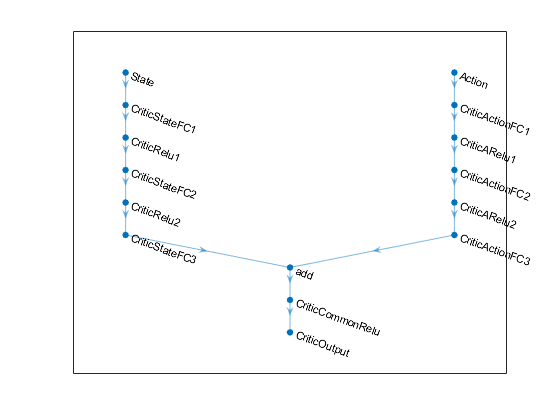

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOpts = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1);

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},criticOpts);

Given observations, a DDPG agent decides which action to take using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Construct the actor in a similar manner to the critic. For more information, see [`rlDeterministicActorRepresentation`](docid:rl_ref#mw_425a8728-2966-45c4-9d2a-488aa4a506bf).

actorNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','State')
    fullyConnectedLayer(3, 'Name','actorFC')
    tanhLayer('Name','actorTanh')
    fullyConnectedLayer(numActions,'Name','Action')
    ];

actorOptions = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);

actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'State'},'Action',{'Action'},actorOptions);

To create the DDPG agent, first specify the DDPG agent options using [rlDDPGAgentOptions](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'DiscountFactor',1.0, ...
    'MiniBatchSize',64, ...
    'ExperienceBufferLength',1e6); 
agentOpts.NoiseOptions.Variance = 0.3;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Then, create the DDPG agent using the specified actor representation, critic representation, and agent options. For more information, see [rlDDPGAgent](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOpts);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most `5000` episodes. Specify that each episode lasts for at most `ceil(Tf/Ts)` (that is `200`) time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than `800` over `20` consecutive episodes. At this point, the agent can control the level of water in the tank.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes, ...
    'MaxStepsPerEpisode',maxsteps, ...
    'ScoreAveragingWindowLength',20, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',800);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load('pmsm.mat','agent')
end

The electrical initial states of your model are forced to zero by the powergui block.


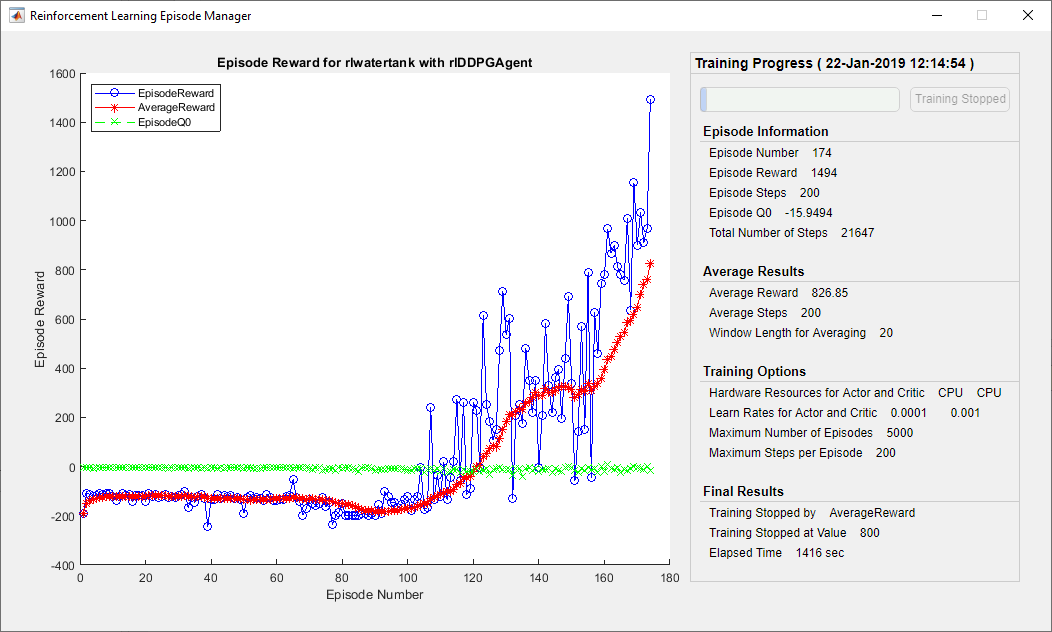

## Validate Trained Agent

Validate the learned agent against the model by simulation.

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');
experiences = sim(env,agent,simOpts);

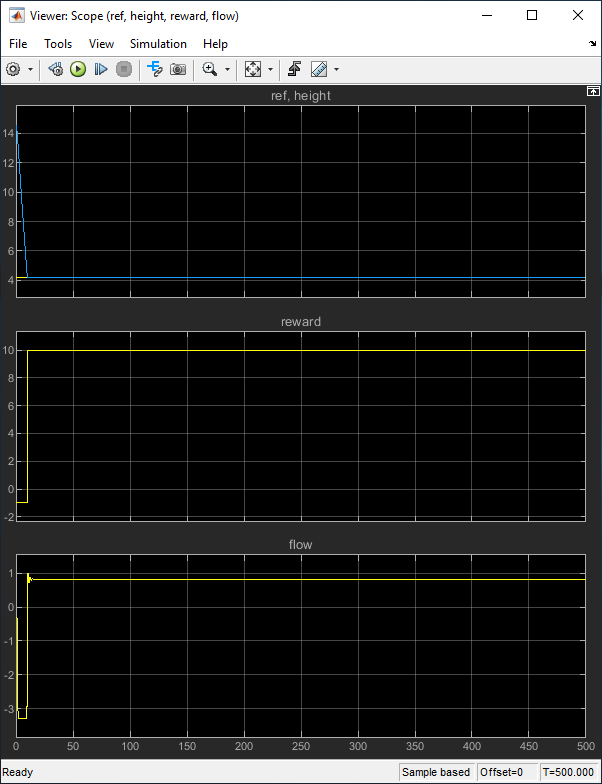

## Local Function

function in = localResetFcn(in)

% randomize reference signal
blk = sprintf('pmsm/Desired \nWater Level');
h = 30*randn + 1000;
in = setBlockParameter(in,blk,'Value',num2str(h));
end

*Copyright 2019 The MathWorks, Inc.*